# Generating an action potential with NEURON in MATLAB

In this example we will start a NEURON session, create a morphology and generate an action potential. 

For the full NEURON documentation, run `doc neuron`.

## Initialize the NEURON session

We need to set up our paths so that we can use the NEURON library. Make sure your NEURON path is listed correctly in `setup_nrn_paths.m`, before running it here.

Then, we can start a NEURON session by calling `n = neuron.Neuron()`. To reset the topology created in a previous run of the live script, we call `n.reset_sections()`. 

All available top-level variables, functions and NEURON objects can be displayed using `n.list_functions()`. These top-level variables, functions and objects are generated dynamically and can be accessed directly, e.g., we can directly call `n.t`, `n.topology()`, and `n.IClamp()`. One important caveat, though, is that the code can crash if incorrect input arguments are provided to dynamically generated functions and object constructors. We hope to fix this in NEURON version 9, in which error handling will be updated.

% Initialization & reset.
clear;                          % Clear MATLAB workspace.
setup;                          % Make sure we can find the NEURON library.
n = neuron.Neuron();            % Initialize the NEURON session.
n.reset_sections();             % Reset topology.
n.list_functions();             % Show available top-level variables, functions

Available variables:
    PI
    E
    GAMMA
    DEG
    PHI
    FARADAY
    R
    Avogadro_constant
    hoc_ac_
    float_epsilon
    hoc_cross_x_
    hoc_cross_y_
    default_dll_loaded_
    xopen_broadcast_
    clamp_resist
    celsius
    secondorder
    diam_changed
    nrn_shape_changed_
    nrn_netrec_state_adjust
    nrn_sparse_partrans
    stoprun
    t
    dt
    nseg
    L
    rallbranch
    Ra
    nai0_na_ion
    nao0_na_ion
    ki0_k_ion
    ko0_k_ion
    minf_hh
    hinf_hh
    ninf_hh
    mtau_hh
    htau_hh
    ntau_hh
    usetable_hh
    ib_IntFire4
    eps_IntFire4
    taueps_IntFire4
Available functions (returning a double):
    atan2
    system
    prmat
    solve
    eqinit
    plt
    axis
    plot
    plotx
    ploty
    regraph
    symbols
    printf
    xred
    sred
    ropen
    wopen
    xopen
    hoc_stdout
    chdir
    fprint
    fscan
    sscanf
    sprint
    graph
    graphmode
    fmenu
    lw
    getstr
    strcmp
    setcolor
    startsw
    stopsw
 

                                % and objects.

## Morphology

Let's create two Sections: an axon and a connected branch. To create a Section with a certain name, use `sec = n.Section(name)`; the section length and its number of segments can be set using `sec.length` and `sec.nseg` respectively. We can also set its diameter (`sec.set_diameter()`) and insert a mechanism (`sec.insert_mechanism()`). To see the list of available insertable mechanisms, see `sec.mech_list`.

Finally, we can display the entire topology with `n.topology()`.

% Make axon.
axon = n.Section("axon");       % Construct a Section.
axon.nseg = 3;                  % Set the number of segments.
axon.set_diameter(50);          % Set the Section diameter.
disp(axon.mech_list);           % Display available insertable mechanisms.

    "morphology"    "capacitance"    "pas"    "extracellular"    "fastpas"    "na_ion"    "k_ion"    "hh"



axon.insert_mechanism("hh");    % Insert a mechanism.

% Connect branch.
branch = n.Section("branch");   % Construct a Section.
branch.set_diameter(10);        % Set the Section diameter.
branch.nseg = 4;                % Set the number of segments.
branch.length = 1000;           % Set the Section length (um).
branch.connect(0, axon, 1);     % Connect the start (0) of the branch
                                % to the end (1) of the axon.

% Show result.
n.topology();                   % Display the resulting topology.

|---|       axon(0-1)
     `---|       branch(0-1)



## Vectors

In NEURON, quantities are recorded with Vectors (`vec = n.Vector()`) In this case we would like to track time and voltage information. The recording method `vec.record(ref)` takes a reference `ref` as input. A reference can be created using `n.ref()` for top-level variables, or `sec.ref()` for a Section `sec`.

Here, the class of `ref` is `clib.neuron.NrnRef`; this class was added to make sure MATLAB handles C++ pointers correctly. You can get/set the value that `ref` points to using `ref.get()` and `ref.set()`, respectively.

% Track time with Vector t_vec.
t_vec = n.Vector();             % Construct a Vector.
disp(n.var_list);               % Display all top-level variables.

  Columns 1 through 12

    "PI"    "E"    "GAMMA"    "DEG"    "PHI"    "FARADAY"    "R"    "Avogadro_constant"    "hoc_ac_"    "float_epsilon"    "hoc_cross_x_"    "hoc_cross_y_"

  Columns 13 through 20

    "default_dll_loaded_"    "xopen_broadcast_"    "clamp_resist"    "celsius"    "secondorder"    "diam_changed"    "nrn_shape_changed_"    "nrn_netrec_state_…"

  Columns 21 through 33

    "nrn_sparse_partrans"    "stoprun"    "t"    "dt"    "nseg"    "L"    "rallbranch"    "Ra"    "nai0_na_ion"    "nao0_na_ion"    "ki0_k_ion"    "ko0_k_ion"    "minf_hh"

  Columns 34 through 42

    "hinf_hh"    "ninf_hh"    "mtau_hh"    "htau_hh"    "ntau_hh"    "usetable_hh"    "ib_IntFire4"    "eps_IntFire4"    "taueps_IntFire4"



t = n.ref("t");                 % Create a reference to the top-level variable t.
t_vec.record(t);                % Record t with the Vector t_vec.

% Track voltage at two points.
v1_vec = n.Vector();            % Construct a Vector.
disp(axon.range_list);          % Display all range variables for the axon.

  Columns 1 through 15

    "v"    "i_membrane_"    "diam"    "cm"    "i_cap"    "g_pas"    "e_pas"    "i_pas"    "xraxial"    "xg"    "xc"    "e_extracellular"    "i_membrane"    "vext"    "g_fastpas"

  Columns 16 through 31

    "e_fastpas"    "ena"    "nai"    "nao"    "ina"    "dina_dv_"    "ek"    "ki"    "ko"    "ik"    "dik_dv_"    "gnabar_hh"    "gkbar_hh"    "gl_hh"    "el_hh"    "gna_hh"

  Columns 32 through 36

    "gk_hh"    "il_hh"    "m_hh"    "h_hh"    "n_hh"



v1 = axon.ref("v", 0.5);        % Create a reference (v1) to the voltage 
                                % at the center of the axon.
v1_vec.record(v1);              % Record v1 with the Vector v1_vec.
v2_vec = n.Vector();            % Construct a Vector.
v2 = branch.ref("v", 1);        % Create a reference (v2) to the voltage
                                % at the end of the branch.
v2_vec.record(v2);              % Record v2 with the Vector v2_vec.

## Putting a current clamp on the axon

We can create a current clamp on the axon using `iclamp = n.IClamp(axon, loc)`, where `loc` is a location on the axon between 0 and 1. This is an example of a dynamically generated NEURON object. Its available attributes and methods can be displayed by calling `iclamp.list_methods()`. 

The attributes and methods of these objects are themselves also generated dynamically. Hence, object properties (such as `del`, `dur`, `amp` in this case) can be set directly.

iclamp = n.IClamp(axon, 0);     % Insert current clamp at start of axon.
iclamp.list_methods();          % List available attributes and methods of a

Available attributes:
    del
    dur
    amp
    i
Available methods (returning a double):
    loc
    has_loc
    get_loc


                                % dynamically generated Neuron Object.
iclamp.del = 0.5;               % Set delay to 0.5ms.
iclamp.dur = 1;                 % Set duration to 1ms.
iclamp.amp = 10;                % Set current amplitude to 10nA.

## Running the simulation

To initialize the simulation with a voltage we call `n.finitialize(voltage)`. Then, we run `n.fadvance()` until the time `n.t` reaches 7 milliseconds.

% Run simulation.
n.finitialize(-65);             % Initialize simulation with a voltage of -65 mV.
n.dt = 0.025;                   % Set the timestep to 0.025 ms.
while n.t < 7                   % Iterate up to t=7 ms.
    if (abs(round(n.t) - n.t) < 1e-6)
        % Print time and current at integer (in ms) time values.
        fprintf('t (ms): %.4f; I (nA): %.4f \n', n.t, iclamp.i);
    end
    n.fadvance();               % Advance the time by n.dt.
end

t (ms): 0.0000; I (nA): 0.0000 
t (ms): 1.0000; I (nA): 10.0000 
t (ms): 2.0000; I (nA): 0.0000 
t (ms): 3.0000; I (nA): 0.0000 
t (ms): 4.0000; I (nA): 0.0000 
t (ms): 5.0000; I (nA): 0.0000 
t (ms): 6.0000; I (nA): 0.0000 


disp("Number of timesteps recorded: " + length(t_vec));

Number of timesteps recorded: 281


## Plotting an action potential

We can plot the resulting action potentials by giving time and voltage recording vectors as inputs to the MATLAB plot function.

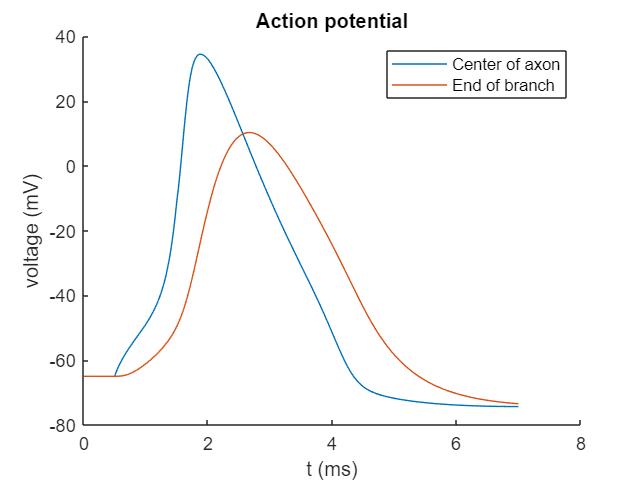

% Plot results.
figure;
hold on;
plot(t_vec, v1_vec);            % Providing a Vector as an input to plot() calls 
                                % Vector.double() in the background.
plot(t_vec, v2_vec);
legend('Center of axon', 'End of branch')
title("Action potential");
xlabel("t (ms)");
ylabel("voltage (mV)");
hold off;